addpath(genpath(fileparts(which('pathfile.m'))))
setup_heli_LQR_parameters
error_data = load('Borrowed_Error_PitchYaw');
state_data_pitch = load('Lab6_state_pitch');
state_data_yaw = load('Lab6_state_yaw');
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);

## Calculations (i)

Ki_error = error_data.Ki

Ki_error =    14.0787    0.6385    6.7848   -0.5032   14.0655    1.8011
   -4.2121   33.5934   -3.2058   22.2114   -2.0797   24.3621


Ki_state = lqr(a, b, diag([0 0 0 7 1 7]), 0.01) 

Ki_state =     4.1315   20.5591    2.8963   14.6438    8.5068   13.9084
   -1.9542   36.8381   -2.3515   29.6949   -5.2569   22.5068



dt = 1e-3*2;

% Pitch Error Feedback Data
etoff_time_pitch = 30;
etoff_pitch = etoff_time_pitch/dt;

e_pitch = error_data.pitch_CH_SE_15pitch.signals.values(etoff_pitch:end,1);
e_pitch_ref = error_data.pitch_CH_SE_15pitch.signals.values(etoff_pitch:end,2);
e_pitch_time = error_data.pitch_CH_SE_30yaw.time(etoff_pitch:end)-etoff_time_pitch;
e_pitch_volt = error_data.voltage_CH_SE_15pitch.signals.values(etoff_pitch:end,2);

% Yaw Error Feedback Data
etoff_time_yaw = 25;
etoff_yaw = etoff_time_yaw/dt;

e_yaw = error_data.yaw_CH_SE_30yaw.signals.values(etoff_yaw:end,1);
e_yaw_ref = error_data.yaw_CH_SE_30yaw.signals.values(etoff_yaw:end,2);
e_yaw_time = error_data.yaw_CH_SE_30yaw.time(etoff_yaw:end)-etoff_time_yaw;
e_yaw_volt = error_data.voltage_CH_SE_30yaw.signals.values(etoff_yaw:end,2);

## Calcuations (ii)

% Pitch State Feedback Data
stoff_time_pitch = 15;
stoff_pitch = stoff_time_pitch/dt;

s_pitch = state_data_pitch.Theta.signals.values(stoff_pitch:end,1);
s_pitch_ref = state_data_pitch.Theta.signals.values(stoff_pitch:end,2);
s_pitch_time = state_data_pitch.Theta.time(stoff_pitch:end)-stoff_time_pitch;
s_pitch_volt = state_data_pitch.Voltage.signals.values(stoff_pitch:end,2);

% Yaw State Feedback Data
stoff_time_yaw = 0;
stoff_yaw = 1;%stoff_time_yaw/dt;

s_yaw = state_data_yaw.Psi.signals.values(stoff_yaw:end,1);
s_yaw_ref = state_data_yaw.Psi.signals.values(stoff_yaw:end,2);
s_yaw_time = state_data_yaw.Psi.time(stoff_yaw:end)-stoff_time_yaw;
s_yaw_volt = state_data_yaw.Voltage.signals.values(stoff_yaw:end,2);


## Plots

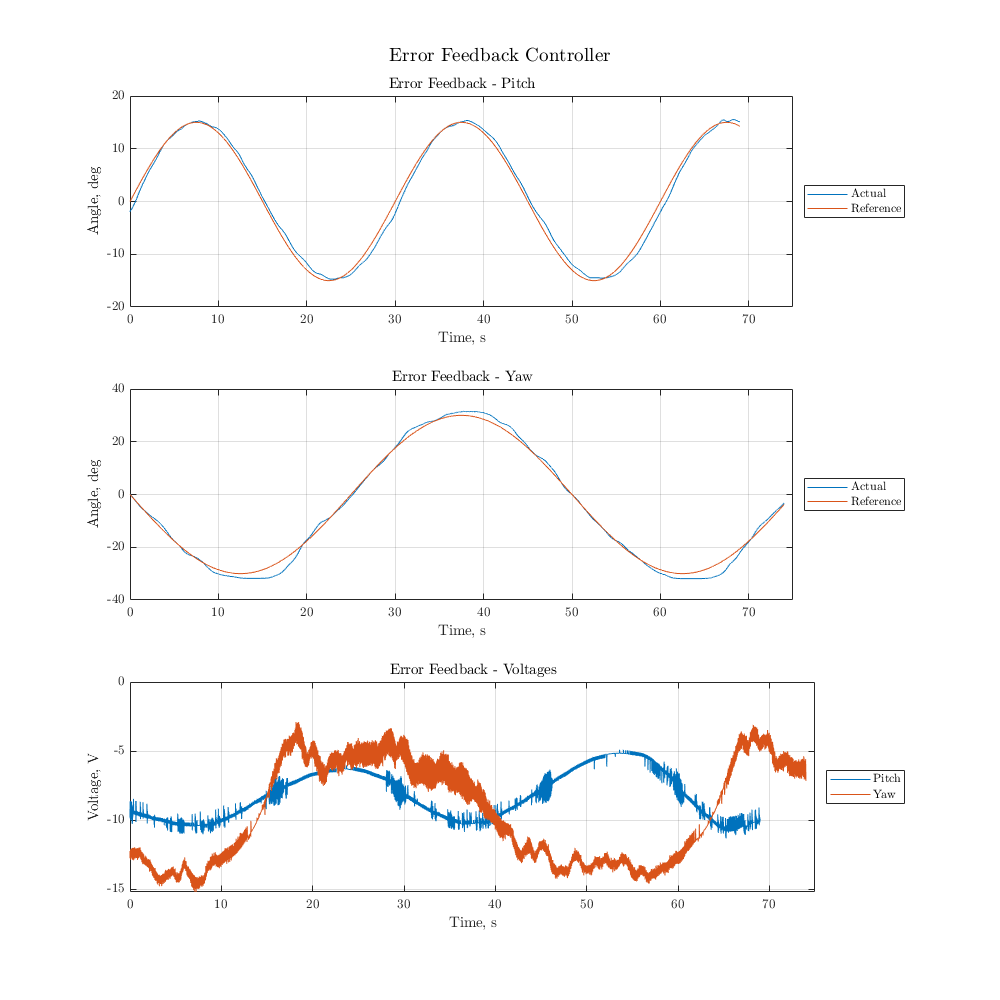

figure(1)
subplot(3,1,1)
plot(e_pitch_time,e_pitch)
hold on
plot(e_pitch_time,e_pitch_ref)
xlim([0 75]), ylim([-20 20])
grid on
title('Error Feedback - Pitch')
xlabel('Time, s')
ylabel('Angle, deg')
legend('Actual','Reference','Location','eastoutside')
hold off

subplot(3,1,2)
plot(e_yaw_time,e_yaw)
hold on
plot(e_yaw_time,e_yaw_ref)
xlim([0 75]), ylim([-40 40])
grid on
title('Error Feedback - Yaw')
xlabel('Time, s')
ylabel('Angle, deg')
legend('Actual','Reference','Location','eastoutside')
hold off

subplot(3,1,3)
plot(e_pitch_time,e_pitch_volt)
hold on
plot(e_yaw_time,e_yaw_volt)
title('Error Feedback - Voltages')
xlabel('Time, s')
ylabel('Voltage, V')
legend('Pitch','Yaw','Location','eastoutside')
xlim([0 75])
grid on
hold off
sgtitle('Error Feedback Controller')
set(gcf,'position',[0,0,1000,1000])

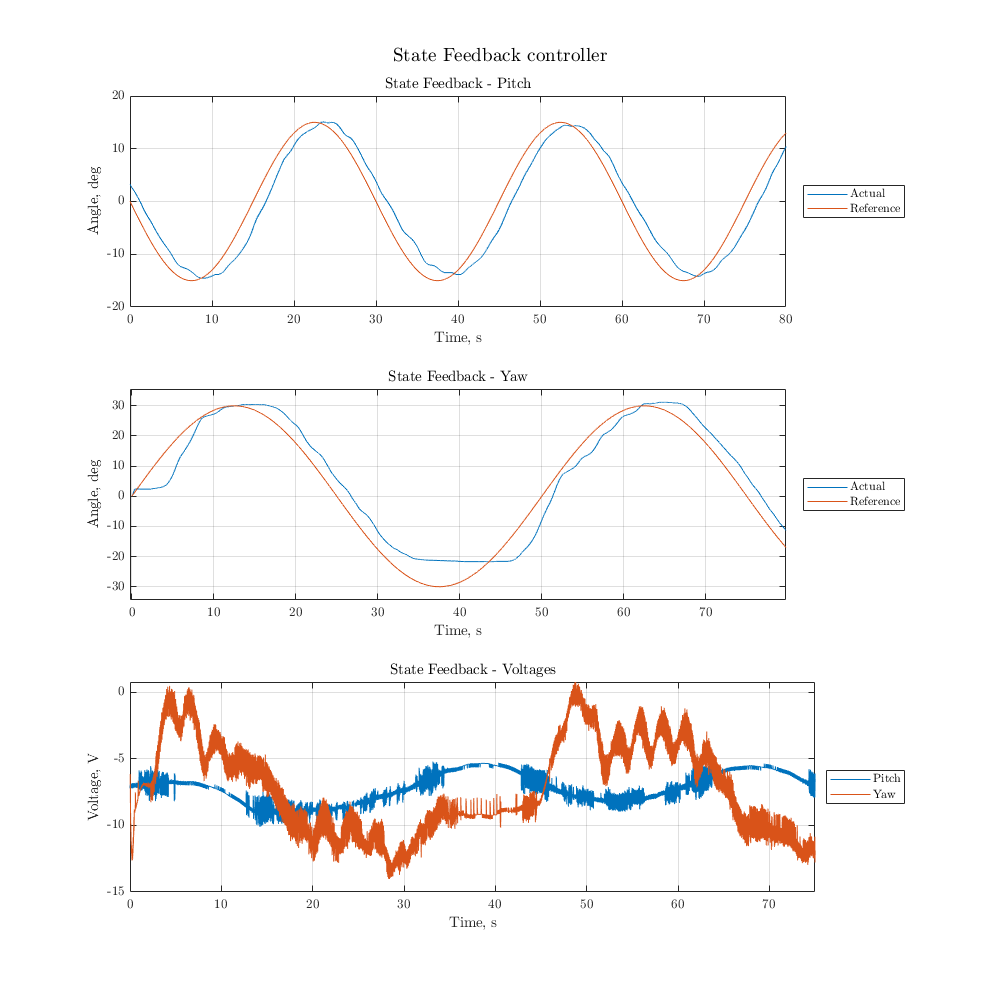



figure(2)
subplot(3,1,1)
plot(s_pitch_time,s_pitch)
hold on
plot(s_pitch_time,s_pitch_ref)
xlim([0 80]), ylim([-20 20])
grid on
title('State Feedback - Pitch')
xlabel('Time, s')
ylabel('Angle, deg')
legend('Actual','Reference','Location','eastoutside')
hold off

subplot(3,1,2)
plot(s_yaw_time,s_yaw)
hold on
plot(s_yaw_time,s_yaw_ref)
xlim([0 80]), ylim([-35 35])
grid on
title('State Feedback - Yaw')
xlabel('Time, s')
ylabel('Angle, deg')
legend('Actual','Reference','Location','eastoutside')
hold off

subplot(3,1,3)
plot(s_pitch_time,s_pitch_volt)
hold on
plot(s_yaw_time,s_yaw_volt)
title('State Feedback - Voltages')
xlabel('Time, s')
ylabel('Voltage, V')
legend('Pitch','Yaw','Location','eastoutside')
xlim([0 75])
grid on
hold off
sgtitle('State Feedback controller')
set(gcf,'position',[0,0,1000,1000])

abse_pitch = abs(e_pitch - e_pitch_ref);
abss_pitch = abs(s_pitch - s_pitch_ref);
abse_yaw = abs(e_yaw - e_yaw_ref);
abss_yaw = abs(s_yaw - s_yaw_ref);
L2_pitch_e = sqrt(1/e_pitch_time(end) * trapz(e_pitch_time,abse_pitch.^2))

L2_pitch_e = 1.0735

L2_yaw_e = sqrt(1/e_yaw_time(end) * trapz(e_yaw_time,abse_yaw.^2))

L2_yaw_e = 1.7334

L2_pitch_s = sqrt(1/s_pitch_time(end) * trapz(s_pitch_time,abss_pitch.^2))  

L2_pitch_s = 3.3386

L2_yaw_s = sqrt(1/s_yaw_time(end) * trapz(s_yaw_time,abss_yaw.^2))

L2_yaw_s = 5.8899

em_pitch_e = max(abse_pitch)

em_pitch_e = 2.4398

em_yaw_e = max(abse_yaw)

em_yaw_e = 4.6100

em_pitch_s = max(abss_pitch)

em_pitch_s = 5.5820

em_yaw_s = max(abss_yaw)

em_yaw_s = 11.4508

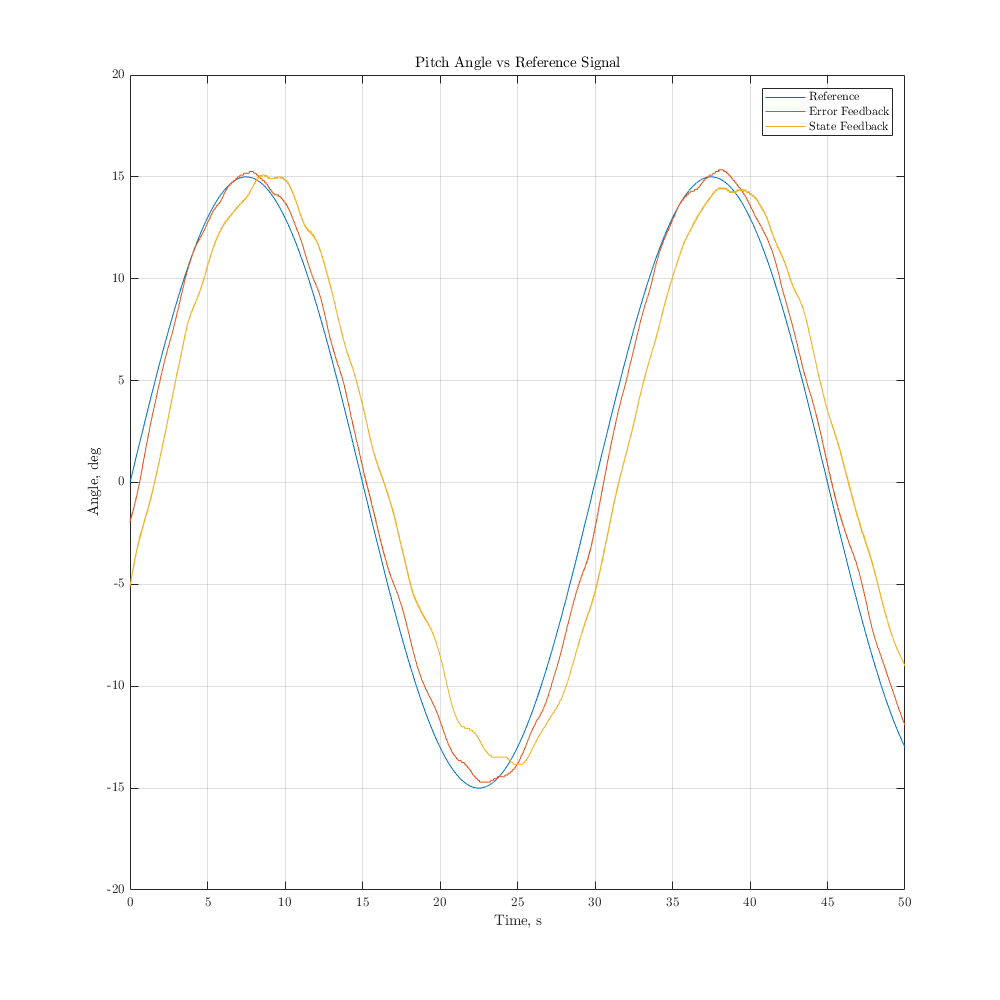

figure(3)
plot(e_pitch_time,e_pitch_ref)
hold on
plot(e_pitch_time,e_pitch)
    stoff_time_pitch = 30;
    stoff_pitch = stoff_time_pitch/dt;
    s_pitch = state_data_pitch.Theta.signals.values(stoff_pitch:end,1);
    s_pitch_time = state_data_pitch.Theta.time(stoff_pitch:end)-stoff_time_pitch;
plot(s_pitch_time,s_pitch)
xlim([0 50]), ylim([-20 20])
grid on
xlabel('Time, s')
ylabel('Angle, deg')
legend('Reference','Error Feedback','State Feedback','Location','best')
title('Pitch Angle vs Reference Signal')
set(gcf,'position',[0,0,1000,1000])

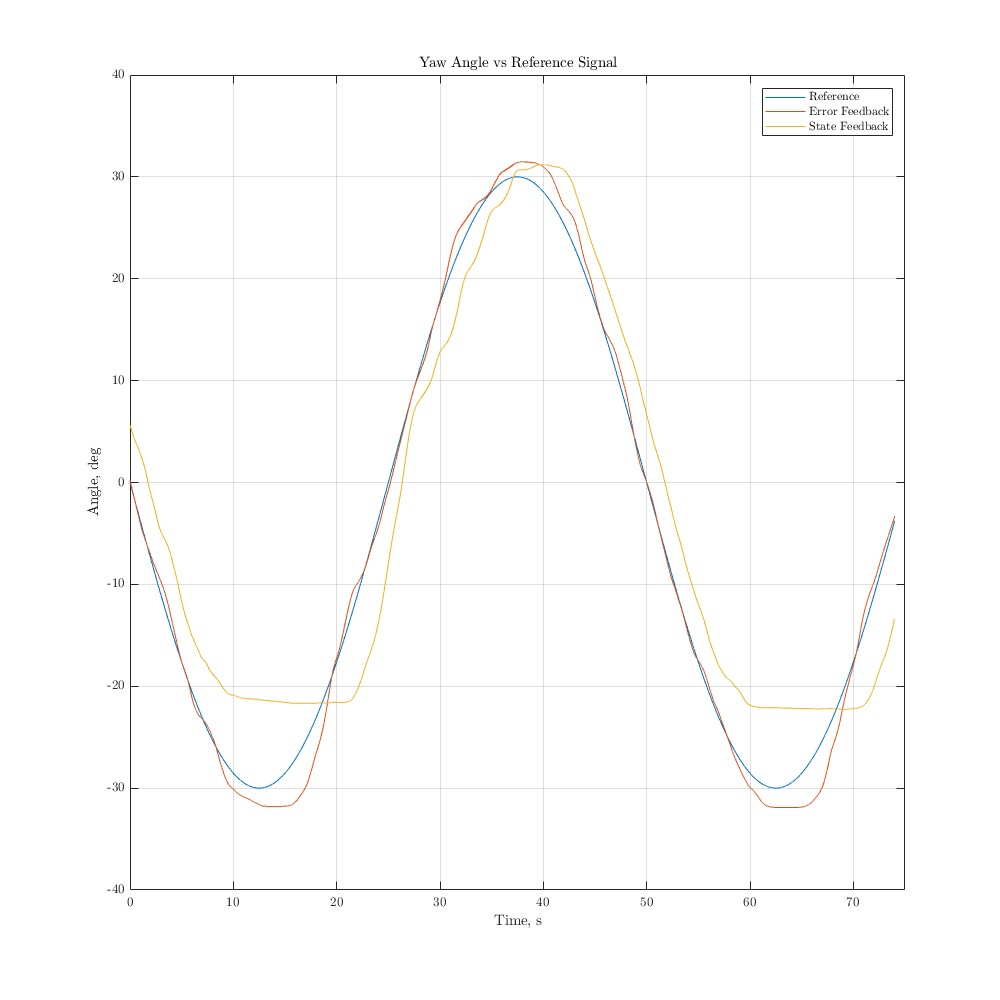

figure(4)
plot(e_yaw_time,e_yaw_ref)
hold on
plot(e_yaw_time,e_yaw)
    stoff_time_yaw = 25;
    stoff_pitch = stoff_time_yaw/dt;
    s_yaw = state_data_yaw.Psi.signals.values(stoff_yaw:end,1);
    s_yaw_time = state_data_yaw.Psi.time(stoff_yaw:end)-stoff_time_yaw;
plot(s_yaw_time,s_yaw)
xlim([0 75])%, ylim([-20 20])
grid on
xlabel('Time, s')
ylabel('Angle, deg')
legend('Reference','Error Feedback','State Feedback','Location','best')
title('Yaw Angle vs Reference Signal')
set(gcf,'position',[0,0,1000,1000])